clc
clear

cd '/users/mkb21147/Documents/Final_PhD_Simulations/Process_Structure_Property_Performance/Structure_Model/examples/Plotting_Microstructure_Evolution'



## Set input file


% temperature_file = '../../input/Abaqus_one_elem_tests/one_elem.csv';
% temperature_file = '../../input/amp_temp_amprin_and_HT900.csv';
% temperature_file = '../../input/XRD_test.csv';



## Run Structure Model

command = append('. ../conda_initialise-3.9.sh && conda activate Process_Simulation_2 && python ./plots_main.py ',temperature_file);
system(command)

Running Structure Model for ../../input/Abaqus_one_elem_tests/one_elem.csv...
Analysis initiated from SIMULIA established products
Abaqus JOB structure_model
Abaqus 2020.HF6
Abaqus License Manager checked out the following licenses:
Abaqus/Standard checked out 5 tokens from Flexnet server abaqus.license.strath.ac.uk.
<456 out of 516 licenses remain available>.
Begin Analysis Input File Processor
Mon 27 May 2024 01:02:15 PM BST
Run pre
Mon 27 May 2024 01:02:17 PM BST
End Analysis Input File Processor
Begin Abaqus/Standard Analysis
Mon 27 May 2024 01:02:17 PM BST
Run standard
Mon 27 May 2024 01:02:20 PM BST
End Abaqus/Standard Analysis
Begin SIM Wrap-up
Mon 27 May 2024 01:02:20 PM BST
Run SMASimUtility
Mon 27 May 2024 01:02:20 PM BST
End SIM Wrap-up
Abaqus JOB structure_model COMPLETED
Abaqus License Manager checked out the following license:
"cae" from Flexnet server abaqus.license.strath.ac.uk
<21 out of 22 licenses remain available>.
Finished Structure Model!


ans = 0

## Plot data

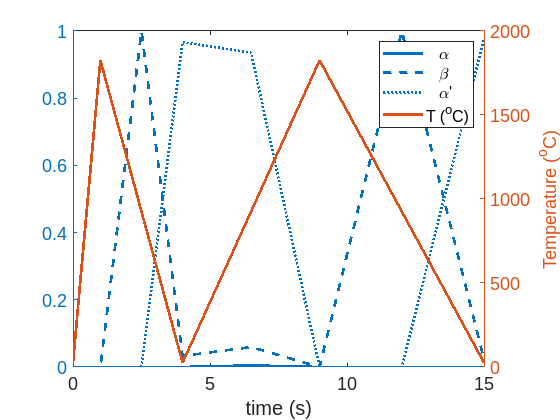

close all

cd data

alpha = readmatrix('alpha.csv');
beta = readmatrix('Beta.csv');
mart = readmatrix('mart.csv');
TEMP = readmatrix('TEMP.csv');
t_lath = readmatrix('t_lath.csv');

time = TEMP(:,1);


%Plot phase fractions
yyaxis left
plot(time, alpha(:,2),'LineWidth',2)
hold on
plot(time, beta(:,2),'LineWidth',2)
plot(time, mart(:,2),'LineWidth',2)
ylabel('Phase Fractions')
hold off

yyaxis right
plot(time, TEMP(:,2),'LineWidth',2)
ylabel('Temperature (^{o}C)')
fontsize(14,"points")
% ylim([0 1650])
% xlim([0 40])

lgnd = legend('   \alpha','   \beta',"   \alpha'",'T (^{o}C)');
xlabel('time (s)')


%Plot lath thickness
yyaxis left
plot(time, t_lath(:,2),'LineWidth',2)

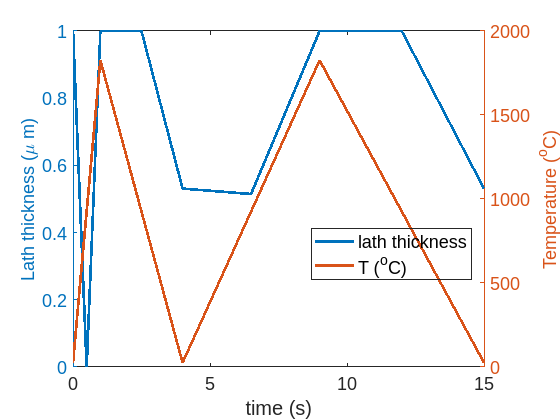


hold on
ylabel('Lath thickness (\mu m)')

yyaxis right
plot(time, TEMP(:,2),'LineWidth',2)
ylabel('Temperature (^{o}C)')

% ylim([0 1650])
fontsize(14,"points")
lgnd = legend('lath thickness','T (^{o}C)');
set(lgnd,'color','none');
xlabel('time (s)')

legend("Position", [0.5915,0.35102,0.21406,0.085034])